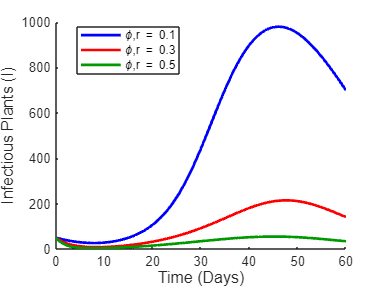

clc;
clear;
close all;

%% ================= TIME =================
tspan = [0 60];

%% ========== INITIAL CONDITIONS ==========
% [S E I R C P]
X0 = [205 100 50 0 10 20];

%% ===== CONTROL LEVELS =====
phi_values = [0.1 0.3 0.5];
v_values   = [0.1 0.3 0.5];

%% ===== COLORS =====
colors = [0 0 1;
          1 0 0;
          0 0.6 0];

%% ================= FIGURE 1 =================
figure;
hold on;

for j = 1:length(phi_values)

    phi = phi_values(j);
    v   = v_values(j);

    [t,X] = ode45(@(t,X) model(t,X,phi,v), tspan, X0);

    I = X(:,3);

    plot(t,I,'LineWidth',2,'Color',colors(j,:));

end

xlabel('Time (Days)','FontSize',12);
ylabel('Infectious Plants (I)','FontSize',12);

legend('{\phi,r} = 0.1',...
       '{\phi,r} = 0.3',...
       '{\phi,r} = 0.5',...
       'Location','best');

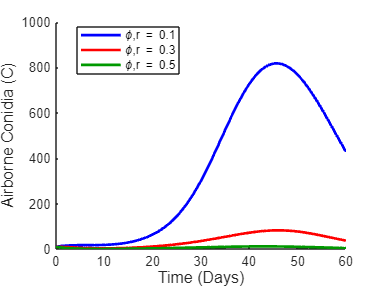




%% ================= FIGURE 2 =================
figure;
hold on;

for j = 1:length(phi_values)

    phi = phi_values(j);
    v   = v_values(j);

    [t,X] = ode45(@(t,X) model(t,X,phi,v), tspan, X0);

    C = X(:,5);

    plot(t,C,'LineWidth',2,'Color',colors(j,:));

end

xlabel('Time (Days)','FontSize',12);
ylabel('Airborne Conidia (C)','FontSize',12);

legend('{\phi,r} = 0.1',...
       '{\phi,r} = 0.3',...
       '{\phi,r} = 0.5',...
       'Location','best');

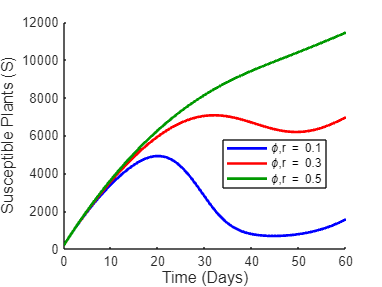




%% ================= FIGURE 3 =================
figure;
hold on;

for j = 1:length(phi_values)

    phi = phi_values(j);
    v   = v_values(j);

    [t,X] = ode45(@(t,X) model(t,X,phi,v), tspan, X0);

    S = X(:,1);

    plot(t,S,'LineWidth',2,'Color',colors(j,:));

end

xlabel('Time (Days)','FontSize',12);
ylabel('Susceptible Plants (S)','FontSize',12);

legend('{\phi,r} = 0.1',...
       '{\phi,r} = 0.3',...
       '{\phi,r} = 0.5',...
       'Location','best');




%% ================= MODEL =================
function dX = model(t,X,phi,v)

%% STATE VARIABLES
S = X(1);
E = X(2);
I = X(3);
R = X(4);
C = X(5);
P = X(6);

%% ================= PARAMETERS =================

Lambda = 400;
mu = 0.018;

betaP0 = 0.02;
betaC0 = 0.002;

omega0 = 0.04;

sigma = 0.005;
eta = 0.01;

gammaMax = 0.8;

psi = 0.0303;
h = 0.018;

delta = 0.2;

theta = 0.002;
muP = 0.03;

%% CONTROL PARAMETERS
epsilon = 0;
kappa = 0;

%% ================= CLIMATE FUNCTIONS =================

T = 25 + 2*sin(2*pi*t/120);

Rain = 20 + 5*sin(2*pi*t/120);

H = 0.85 + 0.05*sin(2*pi*t/120);

M = 0.5 + 0.1*sin(2*pi*t/120);

%% ================= RESPONSE FUNCTIONS =================

fT = exp(-((T-25)^2)/(2*5^2));

fR = (1-exp(-0.3*max(0,Rain)))...
     *exp(-((Rain-20)^2)/(2*10^2));

fH = 1/(1+exp(-30*(H-0.9)));

fM = min(1,M/0.6);

%% ================= EFFECTIVE RATES =================

gamma_t = gammaMax*fT*fH*fR;

omega_t = omega0*fT*fH*fM;

%% Fungicide reduces infection and sporulation
betaP = betaP0*(1-phi)*fM;

betaC = betaC0*(1-phi)*fR*fH;

%% ================= FORCE OF INFECTION =================

d = 1;

lambda = betaP*(P/(d+P)) + betaC*C;

%% ================= MODEL EQUATIONS =================

dS = Lambda - lambda*S - mu*S;

dE = lambda*S - (omega_t + mu)*E;

%% Roguing removes infectious plants
dI = omega_t*E - (sigma + mu + v + eta)*I;

dR = (v + eta)*I - mu*R;

%% Fungicide suppresses conidia production
dC = (1-phi)*gamma_t*I + psi*(P/(h+P)) ...
     - (delta + phi)*C;

dP = theta*I - (muP + kappa)*P;

dX = [dS; dE; dI; dR; dC; dP];

end